# Analysis of Antarctic sectors

There are three sectors available:

- SA := South Africa, 

- WS := Weddell Sea,

-  and EA := East Antarctica

## Table of contents

- Preamble

- Ice concentration (aice)

- Pancake ice concentration

- Pancake ice width

- Pancake ice growth 

- SWH presence

- SWH distance into the ice

- Ice velocities

- Wind and ice relationship

## 1. Preamble

%% Read in the data.
clear
close all
addpath functions
%ncdisp(filename)

% Parameters
sector = "SA";
grid = 'gx1';
filedir = 'cases/sep1to24/history/iceh.2005-09-24.nc';
[lat,lon,row] = grid_read(grid);

% Make sector mask
[len,wid] = size(lat);

## 2. Ice area

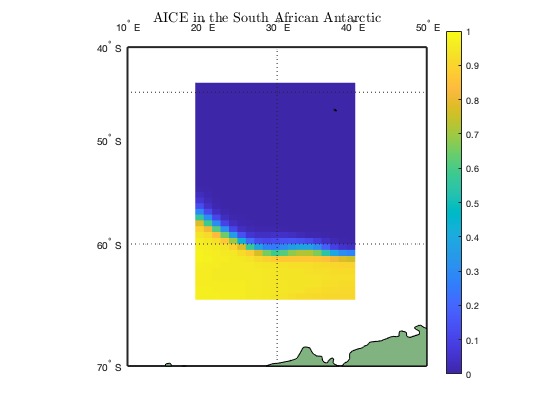

variable = "aice";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
latitude = [-90,-60];
longitude = [10,50];
figure(1)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("AICE in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

## 3. Pancake ice concentration

Floe size categories:

fsd_cats = ncread(filedir,'NFSD');
nfsd = length(fsd_cats);
fprintf('NFSD is: %g', nfsd)

NFSD is: 24

fprintf('The FSD categories are: [');

The FSD categories are: [

fprintf('%g ', fsd_cats);

2.6884 9.79845 21.6721 40.7349 70.1407 113.694 175.577 259.837 369.62 506.24 668.209 850.477 1144.68 1583.1 2147.63 2913.48 3952.43 5361.87 7273.92 9867.81 13386.7 18160.4 24636.4 33421.8 

fprintf(']\n');

]


Define floes with radii $< 10$m as pancakes (i.e., the smallest two FSD categories).

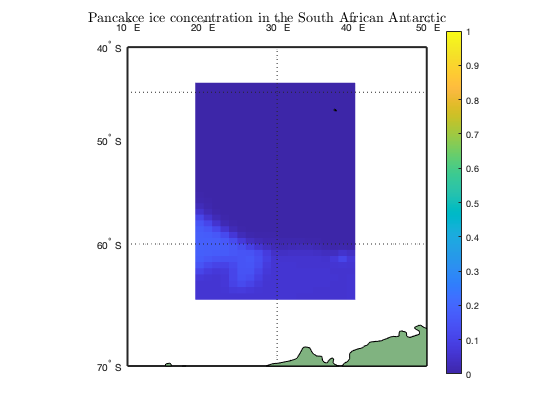

variable = "afsd";
 % Grid
grid = "gx1";
[lat,lon,row] = grid_read(grid);
% Read in data
dim = 3;
data = data_format(filedir,variable,row,lat,lon,dim);
data = data(:,:,1) + data(:,:,2); % Smallest 2 categories combined (ie. pancake)
ocean_mask = data_format(filedir,'tmask',row,lat,lon);
% Coordinates
coords = sector_coords(sector); % (NW;SW,NE,SE) (lat,lon)
for i = 1:4
    [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
end
[len,wid] = size(data);
sector_data = zeros(len,wid);
sector_mask = false(len,wid);
sector_data = ~ocean_mask*NaN;
for i = 0:lat_out(1)-lat_out(2)
    sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
    sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
end


latitude = [-90,-60];
longitude = [10,50];
figure(3)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("Pancakce ice concentration in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

### 3. a) FSD into the ice pack

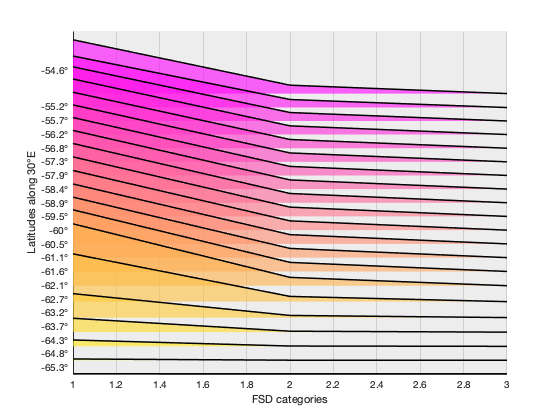

addpath packages/joyPlot
variable = "afsd";
transect_coords = [coords(1,1), (coords(1,2) + coords(3,2))/2];
 % Grid
grid = "gx1";
[lat,lon,row] = grid_read(grid);
% Read in data
dim = 3;
data = data_format(filedir,variable,row,lat,lon,dim);
data_pancake = data(:,:,1) + data(:,:,2); % Smallest 2 categories combined (ie. pancake)
ocean_mask = data_format(filedir,'tmask',row,lat,lon);
% Coordinates
coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon)
for i = 1:4
    [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
end
[len,wid] = size(data_pancake);
sector_data = zeros(len,wid);
sector_mask = false(len,wid);
sector_data = ~ocean_mask*NaN;
for i = 0:lat_out(1)-lat_out(2)
    sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
    sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data_pancake(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
end

[lat_tran,lon_tran] = lat_lon_finder(transect_coords(1),transect_coords(2),lat,lon);

aice = data_format(filedir,'aice',row,lat,lon);
ice_idx = false(1,lat_tran);
for j = lat_tran:-1:1
    if aice(lon_tran,j)>eps
        ice_idx(j) = true;
    end
end
lat_subset = lat(lon_tran,lat_tran:-1:1);

lat_subset_ice = lat_subset(ice_idx);

for j = lat_tran:-1:1
    if ice_idx(j) == 1
        for i = 1:length(fsd_cats)
            transect_fsd(j,i) = data(lon_tran,j,i);
        end
    end
end

transect_fsd_subset = transect_fsd(ice_idx,:);


transect_fsd_threshold = false(1,nfsd);
for i = 1:nfsd
    if sum(transect_fsd(:,i))>0.05
        transect_fsd_threshold(i) = true;
    end
end
Ndecimals = 1; 
f = 10.^Ndecimals; 
for i = 1:length(lat_subset_ice)
    mean_vec(i) = mean(transect_fsd_subset(i,:));
end
transect_fsd_subset_threshold = transect_fsd_subset(:,transect_fsd_threshold);
[len,wid] = size(transect_fsd_subset_threshold);
figure(31)
joyPlot(transect_fsd_subset_threshold',1:wid,0.01,'FaceColor','position','FaceAlpha',0.6)
set(gca,'Color',[0.93 0.93 0.93])
set(gca,'XGrid','on')
colormap(spring)
xlabel("FSD categories")
ylabel(['Latitudes along 30' char(176), 'E'])
% Create a char array with alphabet
lat_lbs = round(f.*lat_subset_ice)./f;
n = size(transect_fsd_subset);
% Formatting
ylbls = sprintfc(['%g', char(176)],lat_lbs(n:-1:1));
% Apply
yticklabels(ylbls)

% title("Cell rest")


## 4. Pancake ice width

## 5. Pancake ice growth

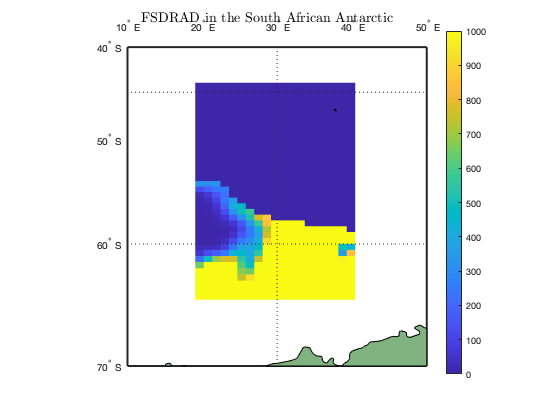

variable = "fsdrad";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
%colormap turbo
latitude = [-90,-60];
longitude = [10,50];
figure(5)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("FSDRAD in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## 6. SWH presence

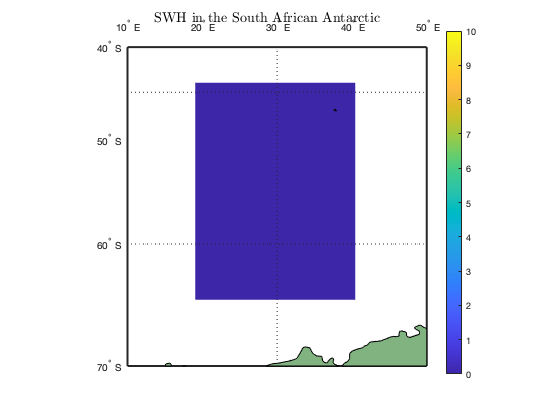

variable = "wave_sig_ht";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
%colormap turbo
latitude = [-90,-60];
longitude = [10,50];
figure(6)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("SWH in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## 7. SWH distance into the ice

## 8. Ice velocities

## 9. Wind and ice velocity relationship

## 10. Ice thickness

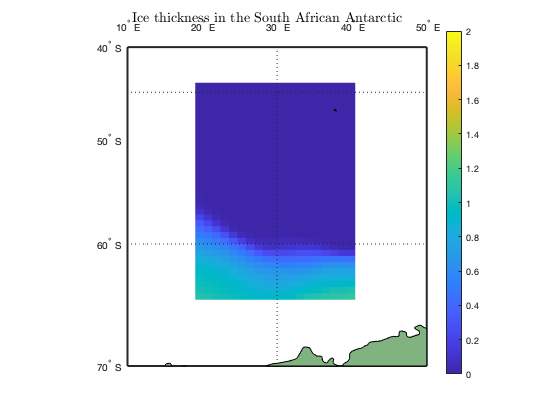

variable = "hi";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
%colormap turbo
latitude = [-90,-60];
longitude = [10,50];
figure(2)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("Ice thickness in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## Functions

function coords = sector_coords(sector)
% Coordinates of sector
%   There are three sectors available:
%       SA := South Africa, 
%       WS := Weddell Sea,
%       and EA := East Antarctica
    if sector == "SA"
        coords = [-45,20;-65,20;-45,40;-65,40]; %(NW;SW,NE,SE)
    elseif sector == "EA"
        coords = [];
    elseif sector == "WS"
        coords = [];
    end
end

function sector_data = data_format_sector(filedir,variable,sector,dim)
     if ~exist('dim', 'var')
        dim = 2; 
     end

    % Grid
    grid = "gx1";
    [lat,lon,row] = grid_read(grid);
    % Read in data
    data = data_format(filedir,variable,row,lat,lon,dim);
    ocean_mask = data_format(filedir,'tmask',row,lat,lon);
    % Coordinates
    coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon)
    for i = 1:4
        [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
    end
    [len,wid] = size(data);
    sector_data = zeros(len,wid);
    sector_mask = false(len,wid);
    sector_data = ~ocean_mask*NaN;
    for i = 0:lat_out(1)-lat_out(2)
        sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
        sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
    end
    
end

function name = sector_name(sector)
    if sector == "SA"
        name = "South African Antarctic";
    elseif sector == "WS"
        name = "Weddell Sea";
    elseif sector == "EA"
        name = "East Antarctic";
    else
        name = "";
        
    end
end
